## EBS 221 Agricultural Robotics

## Spring Quarter 2025

### **Assignment 2**

A. (45 pts). Write a Matlab function that implements a pure-pursuit controller. The function should be called in your main program every DT, and return the steering angle and cross-track error:

`[steer_angle, cross_track_error] = purePursuitController(q, L, Ld, path);`

Use the following parameters: tractor with wheelbase = 2.5 m; γmax = 45o; γmin = - γmax; v = vmax= 1 m/s; τγ = 0.0 s, τv = 0.0 s; dt=1 ms; DT=10 ms.

Initial pose [15 5 π/2]. T = 60.0 s; % maximum simulation time.

clear all;
clc;
type purePursuitController.m;


function [steer_angle, cross_track_error] = purePursuitController(q, L, Ld, path)
    % Extract current state
    x = q(1);
    y = q(2);
    theta = q(3);

    % Find the closest point on the path
    distances = sqrt((path(:,1) - x).^2 + (path(:,2) - y).^2);
    [~, closest_idx] = min(distances);

    % Lookahead goal point: find the first point that is at least Ld away
    goal_idx = closest_idx;
    while goal_idx < size(path,1) && norm([x y] - path(goal_idx,:)) < Ld
        goal_idx = goal_idx + 1;
    end
    
    % If end of path is reached, just use the last point
    if goal_idx >= size(path,1)
        goal_idx = size(path,1);
    end

    goal_point = path(goal_idx, :);

    % Transform goal point to vehicle coordinate frame
    dx = goal_point(1) - x;
    dy = goal_point(2) - y;
    local_x =  cos(theta)*dx + sin(theta)*dy;
    local_y = -sin(theta)*dx + cos(theta)*dy;

    % Compute curvature and steering angle
    curvature = 2 * local_y / (Ld^2);
    steer_angle = atan(L


% Parameters
L = 2.5;
Ld = 2.0;  % can be tuned
dt = 0.001;
DT = 0.01;
T = 60.0;
gamma_max = deg2rad(45);
gamma_min = -gamma_max;

% Initial pose
q = [15; 5; pi/2; 0; 1];  % [x; y; theta; gamma; v]

% Sample path (Nx2 array)
path = [linspace(15, 35, 100)' linspace(5, 25, 100)'];

% Run controller
[steer_angle, cross_track_error] = purePursuitController(q, L, Ld, path);

B. (20 pts)

- Generate points on a circle of radius 5m, centered at (9,7), using this code: a = 0: 0.1 : 2*pi; % angle step for points on circular pathx = 9 + 5*sin(a); y = 7-5*cos(a);

- Write a script that performs closed-loop path tracking to follow the circular path using a look-ahead ld= 2m. Use your robot_bike_dyn.m.

- Plot the cross-track error and the robot’s trace (the trace of the point on the robot’s frame origin).

- Why is the cross-track error nonzero, whereas the robot path looks good? How can you improve the cross-track error calculation?

% 
clear; clc;

type robot_bike_dyn.m;


function q_next = robot_bike_dyn(q, u, umin, umax, Qmin, Qmax, L, tau_gamma, tau_v)
    global dt; 
    global DT;

    % Extract current state
    x     = q(1);
    y     = q(2);
    theta = q(3);
    gamma = q(4);
    v     = q(5);

    % Desired inputs
    gamma_d = u(1);  % desired steering angle
    v_d     = u(2);  % desired velocity

    % Saturate desired inputs
    gamma_d = max(min(gamma_d, umax(1)), umin(1));
    v_d     = max(min(v_d, umax(2)), umin(2));

    % 3) steering dynamics  (τγ = 0  →  instant steer)
    if tau_gamma == 0
        gamma = gamma_d;
    else
        gamma = gamma + dt * (gamma_d - gamma) / tau_gamma;
    end

    % 4) speed dynamics  (τv = 0  →  instant speed change)
    if tau_v == 0
        v = v_d;
    else
        v = v + dt * (v_d - v) / tau_v;
    end

    % Bicycle model kinematics
    dx     = v * cos(theta);
    dy     = v * sin(theta);
    dtheta = v * tan(gamma) / L;

    % Euler integration to update pose
    x     = x + dt * dx;
    y   

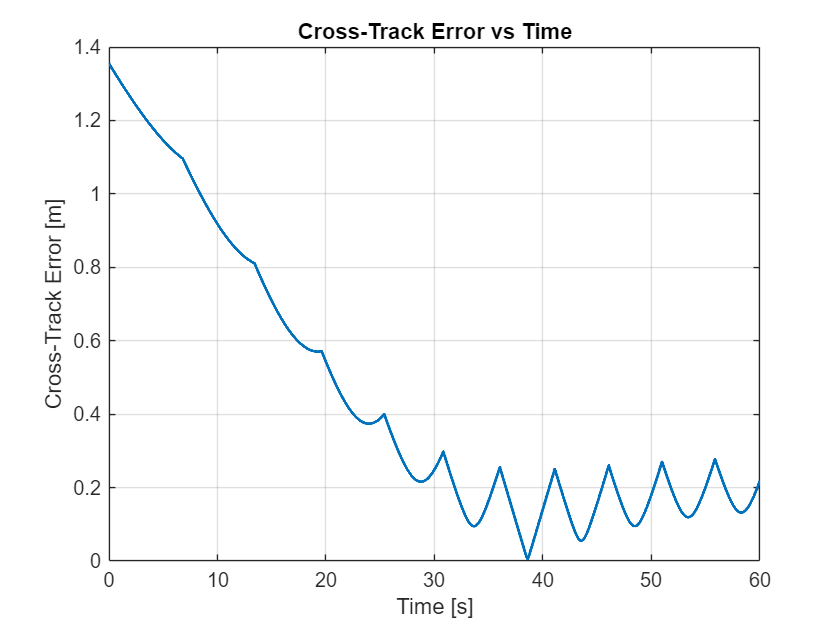


% Global time parameters
global dt DT;
dt = 0.001;   % integration time step
DT = 0.01;    % control update step
T = 60.0;     % max simulation time
time_vec = 0:DT:T;

% Vehicle & control parameters
L = 2.5;               % wheelbase
Ld = 2.0;              % look-ahead distance
gamma_max = deg2rad(45);
gamma_min = -gamma_max;
v_max = 1;
v_min = 0;

% State bounds
Qmax = [inf; inf; inf; gamma_max; v_max];
Qmin = [-inf; -inf; -inf; gamma_min; v_min];

% Initial state [x; y; theta; gamma; v]
q = [15; 5; pi/2; 0; 1];

% Generate circular path: radius 5m, center at (9,7)
a = 0:0.1:2*pi;
path = [9 + 5*sin(a)', 7 - 5*cos(a)'];

% Store results
q_trace = zeros(length(time_vec), 5);
cte_trace = zeros(length(time_vec), 1);

for k = 1:length(time_vec)
    % Control update
    [gamma_d, cte] = purePursuitController(q, L, Ld, path);
    u = [gamma_d; 1.0];  % desired steering angle, constant velocity
    
    % Propagate dynamics using your robot model
    q = robot_bike_dyn(q, u, [gamma_min; v_min], [gamma_max; v_max], Qmin, Qmax, L, 0.0, 0.0);

    % Store data
    q_trace(k, :) = q';
    cte_trace(k) = cte;
end

% === PLOTS ===

% Cross-track error over time
figure;
plot(time_vec, cte_trace, 'LineWidth', 1.5);
xlabel('Time [s]'); ylabel('Cross-Track Error [m]');
title('Cross-Track Error vs Time');
grid on;
saveas(gcf, "figs/circular_cte.png")

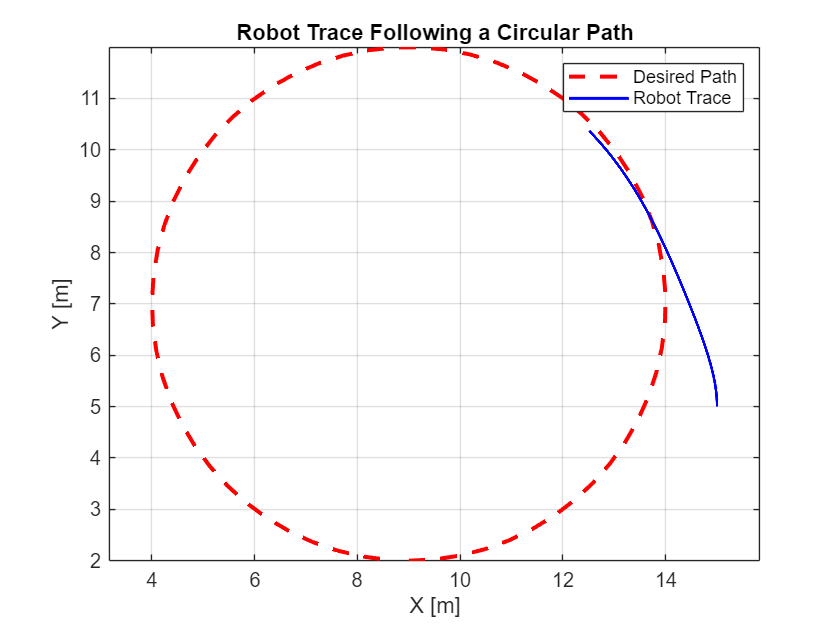

% Robot trace vs circular path
figure;
plot(path(:,1), path(:,2), 'r--', 'LineWidth', 2); hold on;
plot(q_trace(:,1), q_trace(:,2), 'b', 'LineWidth', 1.5);
xlabel('X [m]'); ylabel('Y [m]');
title('Robot Trace Following a Circular Path');
legend('Desired Path', 'Robot Trace');
axis equal;
grid on;

saveas(gcf, "figs/circular_trace.png")

C. (20 pts) 

1. Execute a ‘lane-change’ path scenario, like the one shown below: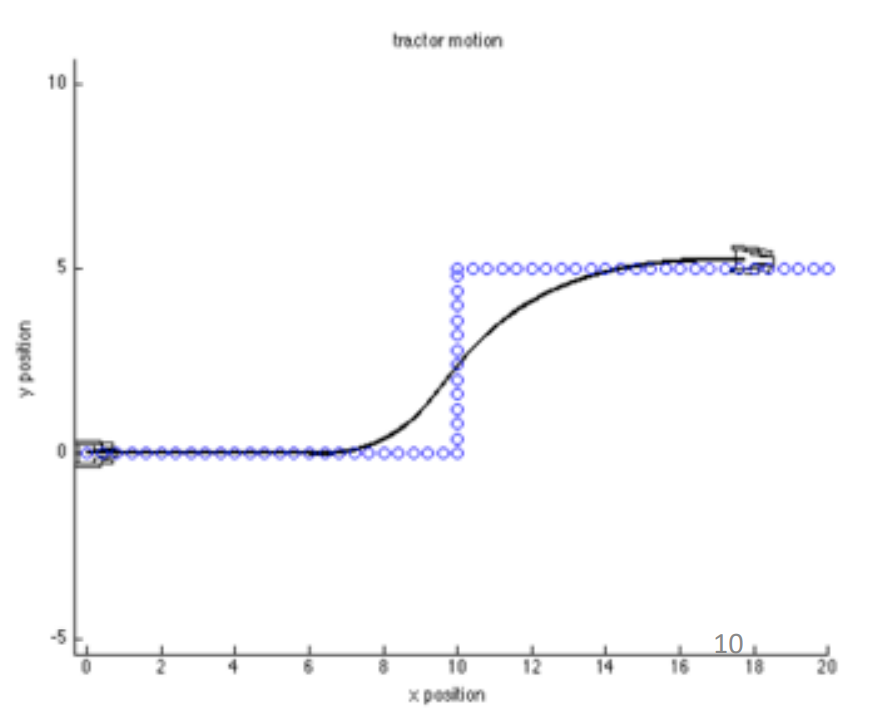

The robot starts at (0,0). The first path segment starts at (0,0). The lengths of the path segments are 10 m (horizontal), 5 m (up), and 10 m (horizontal). 

2. Plot the histogram and find the mean, max, 95th percentile and RMS values of the absolute value of the cross-track error. 

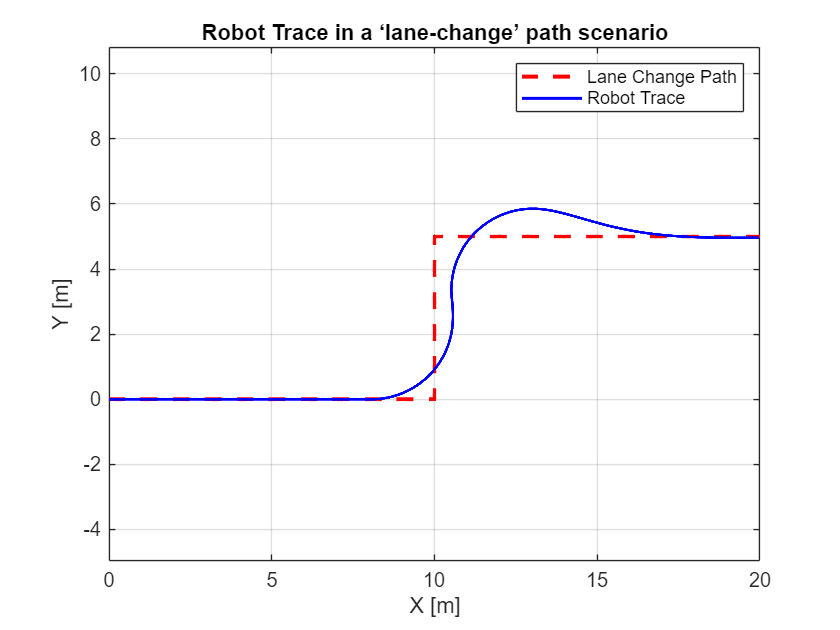

%
clear all;
clc;

% Global time parameters
global dt DT;
dt = 0.001;   % integration time step
DT = 0.01;    % control update step
T = 300.0;     % max simulation time
time_vec = 0:DT:T;

% Vehicle & control parameters
L = 2.5;               % wheelbase
Ld = 2.0;              % look-ahead distance

gamma_max = deg2rad(45);
gamma_min = -gamma_max;
v_max = 1;
v_min = 0;
goal_tol = 0.05;
tau_v = 0;
tau_gamma = 0;

% State bounds
Qmax = [inf; inf; inf; gamma_max; v_max];
Qmin = [-inf; -inf; -inf; gamma_min; v_min];

% Initial state [x; y; theta; gamma; v]
q = [0; 0; 0; 0; 1];
% Generate the lane-change path
init_point = [0; 0];

% Mesh Resolution
dx = 0.01;
dy = 0.01;
seg_hor = 0:dx:10;
seg_ver = 0:dy:5;

% Segment 1: horizontal (0,0) -> (10,0)
path_1 = init_point + [seg_hor; zeros(1, length(seg_hor))];

% Segment 2: Vertical (10,0) -> (10,5)
x1 = path_1(1, end);
y1 = path_1(2, end);
path_2 = [x1; y1] + [zeros(1, length(seg_ver)); seg_ver];

% Segment 3: horizontal (10,5) -> (20,5)
x2 = path_2(1, end);
y2 = path_2(2, end);
path_3 = [x2; y2] + [seg_hor; zeros(1, length(seg_hor))];

% Concatenate the paths (drop the dupcate points)
path = [path_1, path_2(:,2:end), path_3(:,2:end)]';


% Store results
q_trace = zeros(length(time_vec), 5);
cte_trace = zeros(length(time_vec), 1);

for k = 1:length(time_vec)
    % Control update
    [gamma_d, cte] = purePursuitController(q, L, Ld, path);
    u = [gamma_d; 1.0];  % desired steering angle, constant velocity
    
    % Propagate dynamics using your robot model
    q = robot_bike_dyn(q, u, [gamma_min; v_min], [gamma_max; v_max], Qmin, Qmax, L, 0, 0);

    % Store data
    q_trace(k, :) = q';
    cte_trace(k) = cte;
    % goal check
    if norm(q(1:2) - path(end,:).') < goal_tol
        q_trace = q_trace(1:k,:);   % trim unused rows
        break                        % leave the loop
    end
end


% Robot trace on lane change path
figure;
plot(path(:, 1), path(:, 2), 'r--', 'LineWidth', 2); hold on;
plot(q_trace(:,1), q_trace(:,2), 'b', 'LineWidth', 1.5);
xlabel('X [m]'); ylabel('Y [m]');
title('Robot Trace in a ‘lane-change’ path scenario');
legend('Lane Change Path', 'Robot Trace');
axis equal;
grid on;

saveas(gcf, "figs/trace_c2.png")

% Histogram of absolute value of Cross-track error 
% and Cross-track error statistics

abs_cte = abs(cte_trace);                      % magnitude of the error

% Numerical metrics
cte_mean  = mean(abs_cte);                     % arithmetic mean
cte_max   = max(abs_cte);                      % maximum value
cte_p95   = prctile(abs_cte, 95);              % 95th percentile
cte_rms   = rms(abs_cte);                      % root-mean-square

fprintf('\nCTE statistics (m)\n');


CTE statistics (m)


fprintf('  Mean      : %.4f\n', cte_mean);

  Mean      : 0.1819


fprintf('  Max       : %.4f\n', cte_max);

  Max       : 0.8546


fprintf('  95th perc : %.4f\n', cte_p95);

  95th perc : 0.7533


fprintf('  RMS       : %.4f\n', cte_rms);

  RMS       : 0.3176


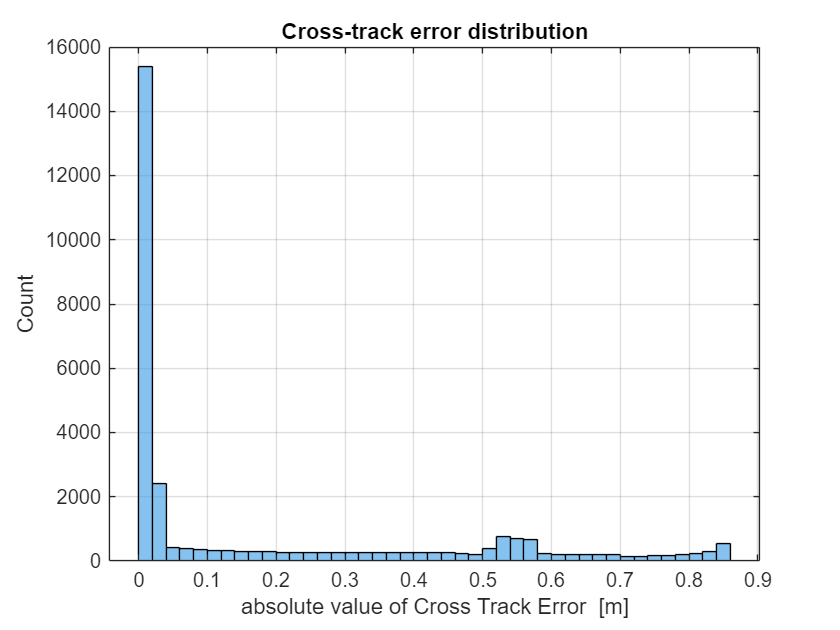


% Histogram plot
figure;  
histogram(abs_cte, 'BinMethod','fd', 'FaceColor',[0.2 0.6 0.9]);
grid on;  xlabel('absolute value of Cross Track Error  [m]');  ylabel('Count');
title('Cross-track error distribution');
saveas(gcf, "figs/hist_c2.png")

3. Explore different values of ld at a fixed speed and comment on path tracking smoothness, stability, and corner-cutting. 

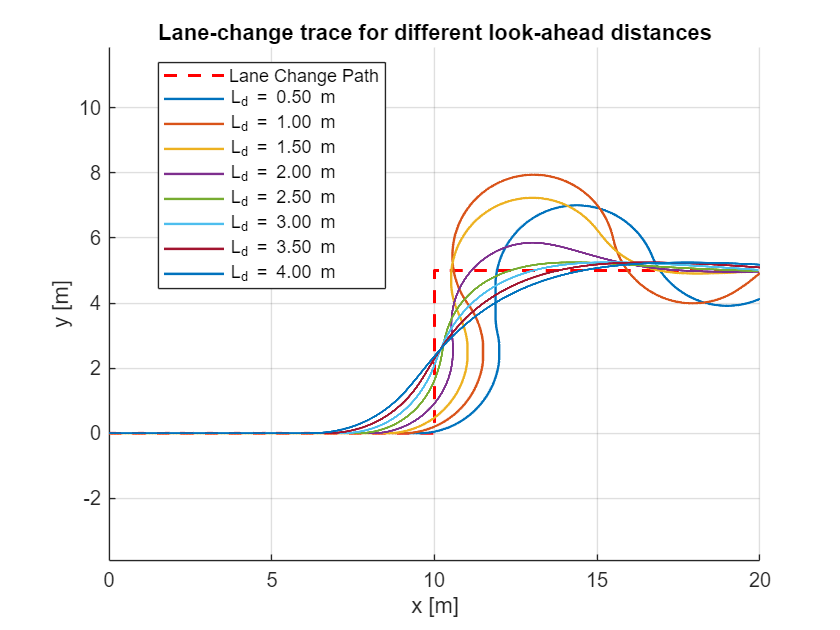

%% Sweep look-ahead L_d and log results
Ld_list  = 0.5 : 0.5 : 4.0;         % [m]
goal_tol = 0.05;                     % stop within 5 cm of goal

% Cell arrays to hold the traces for each run
trace = cell(numel(Ld_list),1);      % pose history
cte   = cell(numel(Ld_list),1);      % cross-track error history

for i = 1:numel(Ld_list)

    Ld  = Ld_list(i);
    q   = [0; 0; 0; 0; 1];                 % [x y θ γ v]  start pose

    q_tr   = zeros(length(time_vec),5);    % pre-allocate once per run
    cte_tr = zeros(length(time_vec),1);
    gamma_hist = zeros(length(time_vec),1);
    for k = 1:length(time_vec)
        % Control update
        [gamma_d, cte_k] = purePursuitController(q, L, Ld, path);
        u = [gamma_d ; 1.0];               % constant 1 m/s

        % Propagate dynamics using robot model
        q = robot_bike_dyn(q, u, ...
                           [-gamma_max; 0], [gamma_max; 1], ...
                           Qmin, Qmax, L, 0, 0);

        % Store data
        q_tr(k,:)   = q.';
        cte_tr(k)   = cte_k;
        gamma_hist(k) = q(4);

        % goal check
        if norm(q(1:2) - path(end,:).') < goal_tol || q(1) > path(end, 1)
            q_tr   = q_tr(1:k,:);          % trim unused rows
            cte_tr = cte_tr(1:k);
            break
        end
    end
    dt_local      = dt;                           % integration step
    steer_rate    = diff(gamma_hist)./dt_local;   % γ̇[k]
    Sdotg(i)      = sum( steer_rate.^2 ) * dt_local;
    rms_cte(i)    = sqrt( mean( cte_tr.^2 ) );
    trace{i} = q_tr;                       % store in cell
    cte{i}   = cte_tr;
end

%% Visualise all runs on one figure
figure; hold on; axis equal; grid on
plot(path(:,1), path(:,2), 'r--', 'LineWidth',1.5, ...
     'DisplayName','Lane Change Path');

cmap = lines(numel(Ld_list));               % distinct colors
for i = 1:numel(Ld_list)
    plot(trace{i}(:,1), trace{i}(:,2), ...
         'Color',cmap(i,:), 'LineWidth',1.2, ...
         'DisplayName', sprintf('L_d = %.2f m', Ld_list(i)));
    legend(Location="best")
end
legend show
xlabel('x [m]'); ylabel('y [m]');
title('Lane-change trace for different look-ahead distances');
saveas(gcf, "figs/trace_c3.png")

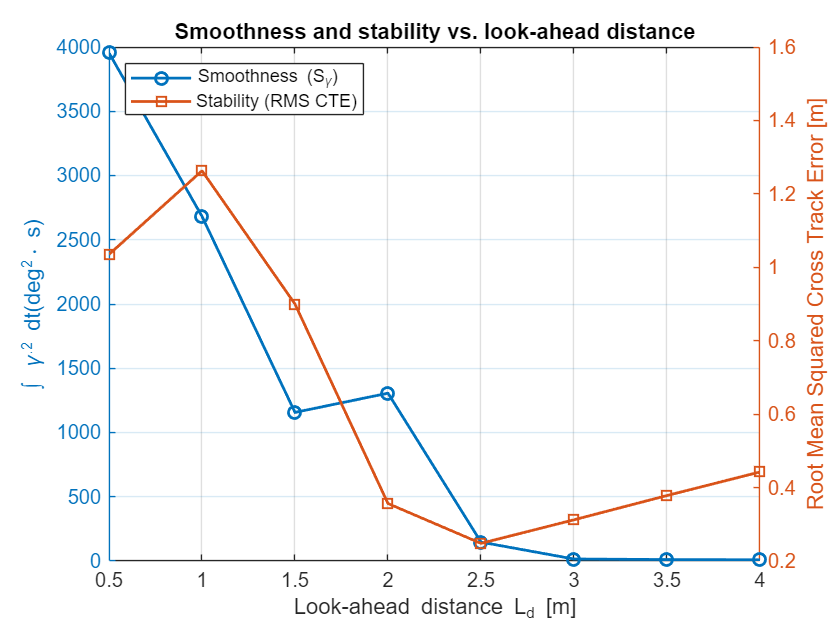


figure; 
yyaxis left
plot(Ld_list, Sdotg, '-o', 'LineWidth', 1.4);
ylabel('\int \gamma^{.2} dt(deg^2\cdot s)', 'Interpreter', 'tex');
yyaxis right
plot(Ld_list, rms_cte, '-s', 'LineWidth', 1.4);
ylabel('Root Mean Squared Cross Track Error [m]');
xlabel('Look-ahead distance L_d [m]', 'Interpreter', 'tex');
title('Smoothness and stability vs. look-ahead distance');
grid on
legend({'Smoothness (S_{\gamma})','Stability (RMS CTE)'}, ...
    'Location', 'northwest', 'Interpreter', 'tex');
saveas(gcf, 'figs/ld_smooth_stab.png')

4. Double the speed. Should ld change?

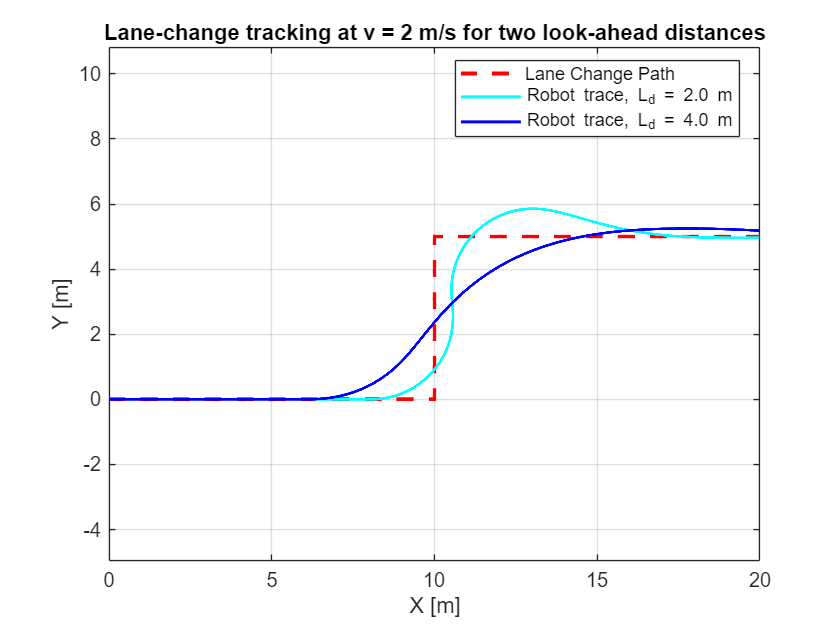

% Vehicle & control parameters
L = 2.5;               % wheelbase
Ld = [2.0; 4.0];              % look-ahead distance

gamma_max = deg2rad(45);
gamma_min = -gamma_max;
v_max = 2;             % Speed is double now (previous 1m/s)
v_min = 0;
goal_tol = 0.05;
tau_v = 0;
tau_gamma = 0;

% State bounds
Qmax = [inf; inf; inf; gamma_max; v_max];
Qmin = [-inf; -inf; -inf; gamma_min; v_min];

% Initial state [x; y; theta; gamma; v]
q = [0; 0; 0; 0; 1];
% Generate the lane-change path
init_point = [0; 0];

% Mesh Resolution
dx = 0.01;
dy = 0.01;
seg_hor = 0:dx:10;
seg_ver = 0:dy:5;

% Segment 1: horizontal (0,0) -> (10,0)
path_1 = init_point + [seg_hor; zeros(1, length(seg_hor))];

% Segment 2: Vertical (10,0) -> (10,5)
x1 = path_1(1, end);
y1 = path_1(2, end);
path_2 = [x1; y1] + [zeros(1, length(seg_ver)); seg_ver];

% Segment 3: horizontal (10,5) -> (20,5)
x2 = path_2(1, end);
y2 = path_2(2, end);
path_3 = [x2; y2] + [seg_hor; zeros(1, length(seg_hor))];

% Concatenate the paths (drop the dupcate points)
path = [path_1, path_2(:,2:end), path_3(:,2:end)]';


% Store results
q_trace = zeros(length(time_vec), 5);
cte_trace = zeros(length(time_vec), 1);

for k = 1:length(time_vec)
    % Control update
    [gamma_d, cte] = purePursuitController(q, L, Ld(1), path);
    u = [gamma_d; 2.0];  % desired steering angle, constant velocity (double the speed)
    
    % Propagate dynamics using your robot model
    q = robot_bike_dyn(q, u, [gamma_min; v_min], [gamma_max; v_max], Qmin, Qmax, L, 0, 0);

    % Store data
    q_trace(k, :) = q';
    cte_trace(k) = cte;
    % goal check
    if norm(q(1:2) - path(end,:).') < goal_tol || q(1) > path(end, 1)
        q_trace = q_trace(1:k,:);   % trim unused rows
        break                        % leave the loop
    end
end


% Robot trace on lane change path
figure;
plot(path(:, 1), path(:, 2), 'r--', 'LineWidth', 2, 'DisplayName', "Lane Change Path"); 
hold on;
plot(q_trace(:,1), q_trace(:,2), 'b', 'LineWidth', 1.5, 'DisplayName', sprintf('Robot trace, L_d = %.1f m', Ld(1)), 'Color', 	"cyan");
xlabel('X [m]'); ylabel('Y [m]');
title('Lane-change tracking at v = 2 m/s for two look-ahead distances');
axis equal;
grid on;
hold on;

% reinstate Initial state
q = [0; 0; 0; 0; 1];
q_trace = zeros(length(time_vec), 5);
cte_trace = zeros(length(time_vec), 1);

for k = 1:length(time_vec)
    % Control update
    [gamma_d, cte] = purePursuitController(q, L, Ld(2), path);
    u = [gamma_d; 2.0];  % desired steering angle, constant velocity (double the speed)
    
    % Propagate dynamics using your robot model
    q = robot_bike_dyn(q, u, [gamma_min; v_min], [gamma_max; v_max], Qmin, Qmax, L, 0, 0);

    % Store data
    q_trace(k, :) = q';
    cte_trace(k) = cte;
    % goal check
    if norm(q(1:2) - path(end,:).') < goal_tol || q(1) > path(end, 1)
        q_trace = q_trace(1:k,:);   % trim unused rows
        break                        % leave the loop
    end
end


% Robot trace on lane change path
plot(q_trace(:,1), q_trace(:,2), 'b', 'LineWidth', 1.5, 'DisplayName', sprintf('Robot trace, L_d = %.1f m', Ld(2)), 'Color', 'b');
xlabel('X [m]'); ylabel('Y [m]');
legend(Location="best")
axis equal;
grid on;
hold on;
saveas(gcf, "figs/trace_c4.png")

D. (15 pts) 1. Introduce: τγ = 0.15 s, τv = 0.5 s. Select a look-ahead distance, ld, and compare the resulting path with the robot path with instantaneous dynamics (τγ = 0.0 s, τv = 0.0 s) and the same ld. 

%
clear all;
clc;

% Global time parameters
global dt DT;
dt = 0.001;   % integration time step   
DT = 0.01;    % control update step
T = 300.0;     % max simulation time
time_vec = 0:DT:T;

% Vehicle & control parameters
L = 2.5;               % wheelbase
Ld = 2.0;              % look-ahead distance

gamma_max = deg2rad(45);
gamma_min = -gamma_max;
v_max = 1;
v_min = 0;
goal_tol = 0.05;
tau_v = [0, 0.5];
tau_gamma = [0, 0.15];

% State bounds
Qmax = [inf; inf; inf; gamma_max; v_max];
Qmin = [-inf; -inf; -inf; gamma_min; v_min];

% Initial state [x; y; theta; gamma; v]
q = [0; 0; 0; 0; 1];
% Generate the lane-change path
init_point = [0; 0];

% Mesh Resolution
dx = 0.01;
dy = 0.01;
seg_hor = 0:dx:10;
seg_ver = 0:dy:5;

% Segment 1: horizontal (0,0) -> (10,0)
path_1 = init_point + [seg_hor; zeros(1, length(seg_hor))];

% Segment 2: Vertical (10,0) -> (10,5)
x1 = path_1(1, end);
y1 = path_1(2, end);
path_2 = [x1; y1] + [zeros(1, length(seg_ver)); seg_ver];

% Segment 3: horizontal (10,5) -> (20,5)
x2 = path_2(1, end);
y2 = path_2(2, end);
path_3 = [x2; y2] + [seg_hor; zeros(1, length(seg_hor))];

% Concatenate the paths (drop the dupcate points)
path = [path_1, path_2(:,2:end), path_3(:,2:end)]';


% Store results
q_trace = zeros(length(time_vec), 5);
cte_trace = zeros(length(time_vec), 1);

% Robot trace on lane change path
figure;
plot(path(:, 1), path(:, 2), 'r--', 'LineWidth', 2, 'DisplayName', "Lane Change Path"); 
hold on;
cmap = lines(2);
for i = 1:length(tau_gamma)
    % reinstate Initial state
    q = [0; 0; 0; 0; 1];
    q_trace = zeros(length(time_vec), 5);
    cte_trace = zeros(length(time_vec), 1);
    for k = 1:length(time_vec)
        % Control update
        [gamma_d, cte] = purePursuitController(q, L, Ld, path);
        u = [gamma_d; 1.0];  % desired steering angle, constant velocity
        
        % Propagate dynamics using your robot model
        q = robot_bike_dyn(q, u, [gamma_min; v_min], [gamma_max; v_max], Qmin, Qmax, L, tau_gamma(i), tau_v(i));
    
        % Store data
        q_trace(k, :) = q';
        cte_trace(k) = cte;
        % goal check
        if norm(q(1:2) - path(end,:).') < goal_tol || q(1) > path(end, 1)
            q_trace = q_trace(1:k,:);   % trim unused rows
            break                        % leave the loop
        end
    end
    plot(q_trace(:,1), q_trace(:,2), 'b', 'LineWidth', 1.5, 'Color', cmap(i,:), 'DisplayName', sprintf('Robot trace, τγ = %.2f m/s, τv = %.1f m/s', tau_gamma(i), tau_v(i)));
    xlabel('X [m]'); ylabel('Y [m]');
    title('Lane-change tracking at l_d = 2 m','for two pairs of steering and speed dynamics');
    legend("Location", "best")
    axis equal;
    grid on;
    hold on;

    % Quantitative Analysis
    abs_cte = abs(cte_trace);                      % magnitude of the error
    
    % Numerical metrics
    cte_mean  = mean(abs_cte);                     % arithmetic mean
    cte_max   = max(abs_cte);                      % maximum value
    cte_p95   = prctile(abs_cte, 95);              % 95th percentile
    cte_rms   = rms(abs_cte);                      % root-mean-square
    
    fprintf(sprintf('\nCTE statistics τγ = %.2f m/s, τv = %.1f m/s \n', tau_gamma(i), tau_v(i)));
    fprintf('  Mean      : %.4f\n', cte_mean);
    fprintf('  Max       : %.4f\n', cte_max);
    fprintf('  95th perc : %.4f\n', cte_p95);
    fprintf('  RMS       : %.4f\n', cte_rms);
    
end


CTE statistics τγ = 0.00 m/s, τv = 0.0 m/s 


  Mean      : 0.1819


  Max       : 0.8546


  95th perc : 0.7533


  RMS       : 0.3176



CTE statistics τγ = 0.15 m/s, τv = 0.5 m/s 


  Mean      : 0.2675


  Max       : 1.3308


  95th perc : 1.2192


  RMS       : 0.4737


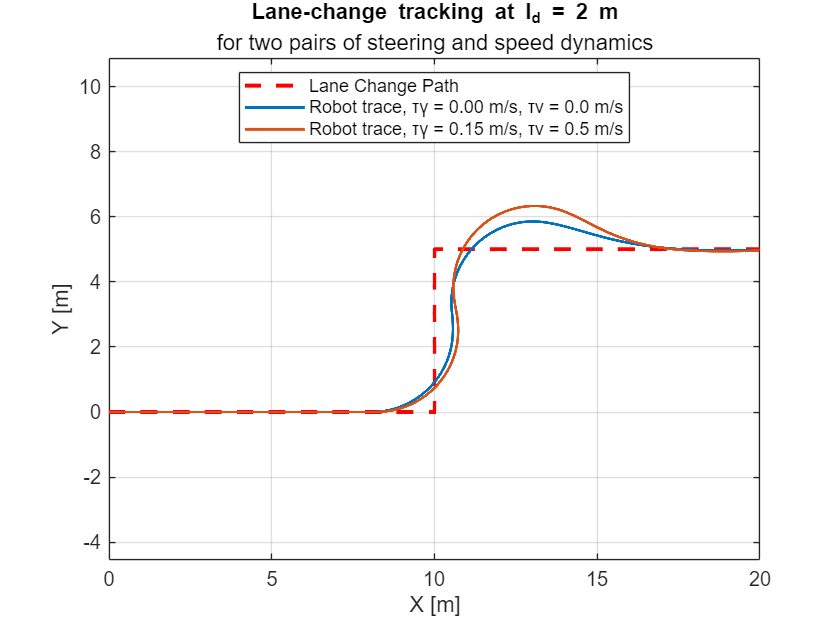



saveas(gcf, "figs/trace_d1.png")

2. Double the steering time lag and observe and report the effects. 

%
clear all;
clc;

% Global time parameters
global dt DT;
dt = 0.001;   % integration time step
DT = 0.01;    % control update step
T = 300.0;     % max simulation time
time_vec = 0:DT:T;

% Vehicle & control parameters
L = 2.5;               % wheelbase
Ld = 2.0;              % look-ahead distance

gamma_max = deg2rad(45);
gamma_min = -gamma_max;
v_max = 1;
v_min = 0;
goal_tol = 0.05;
tau_v = 0;
tau_gamma = [0.15, 0.3];% Double steering time lag

% State bounds
Qmax = [inf; inf; inf; gamma_max; v_max];
Qmin = [-inf; -inf; -inf; gamma_min; v_min];

% Initial state [x; y; theta; gamma; v]
q = [0; 0; 0; 0; 1];
% Generate the lane-change path
init_point = [0; 0];

% Mesh Resolution
dx = 0.01;
dy = 0.01;
seg_hor = 0:dx:10;
seg_ver = 0:dy:5;

% Segment 1: horizontal (0,0) -> (10,0)
path_1 = init_point + [seg_hor; zeros(1, length(seg_hor))];

% Segment 2: Vertical (10,0) -> (10,5)
x1 = path_1(1, end);
y1 = path_1(2, end);
path_2 = [x1; y1] + [zeros(1, length(seg_ver)); seg_ver];

% Segment 3: horizontal (10,5) -> (20,5)
x2 = path_2(1, end);
y2 = path_2(2, end);
path_3 = [x2; y2] + [seg_hor; zeros(1, length(seg_hor))];

% Concatenate the paths (drop the dupcate points)
path = [path_1, path_2(:,2:end), path_3(:,2:end)]';


% Store results
q_trace = zeros(length(time_vec), 5);
cte_trace = zeros(length(time_vec), 1);

% Robot trace on lane change path
figure;
plot(path(:, 1), path(:, 2), 'r--', 'LineWidth', 2, 'DisplayName', "Lane Change Path"); 
hold on;
cmap = lines(2);
for i = 1:length(tau_gamma)
    % reinstate Initial state
    q = [0; 0; 0; 0; 1];
    q_trace = zeros(length(time_vec), 5);
    cte_trace = zeros(length(time_vec), 1);
    for k = 1:length(time_vec)
        % Control update
        [gamma_d, cte] = purePursuitController(q, L, Ld, path);
        u = [gamma_d; 1.0];  % desired steering angle, constant velocity
        
        % Propagate dynamics using your robot model
        q = robot_bike_dyn(q, u, [gamma_min; v_min], [gamma_max; v_max], Qmin, Qmax, L, tau_gamma(i), tau_v);
    
        % Store data
        q_trace(k, :) = q';
        cte_trace(k) = cte;
        % goal check
        if norm(q(1:2) - path(end,:).') < goal_tol || q(1) > path(end, 1)
            q_trace = q_trace(1:k,:);   % trim unused rows
            break                        % leave the loop
        end
    end
    plot(q_trace(:,1), q_trace(:,2), 'b', 'LineWidth', 1.5, 'Color', cmap(i,:), 'DisplayName', sprintf('Robot trace, τγ = %.2f m/s, τv = %.1f m/s', tau_gamma(i), tau_v));
    xlabel('X [m]'); ylabel('Y [m]');
    title('Lane-change tracking at l_d = 2 m', 'for two pairs of steering and speed dynamics');
    legend("Location", "best")
    axis equal;
    grid on;
    hold on;

    % Quantitative Analysis
    abs_cte = abs(cte_trace);                      % magnitude of the error
    
    % Numerical metrics
    cte_mean  = mean(abs_cte);                     % arithmetic mean
    cte_max   = max(abs_cte);                      % maximum value
    cte_p95   = prctile(abs_cte, 95);              % 95th percentile
    cte_rms   = rms(abs_cte);                      % root-mean-square
    
    fprintf(sprintf('\nCTE statistics τγ = %.2f m/s, τv = %.1f m/s \n', tau_gamma(i), tau_v));
    fprintf('  Mean      : %.4f\n', cte_mean);
    fprintf('  Max       : %.4f\n', cte_max);
    fprintf('  95th perc : %.4f\n', cte_p95);
    fprintf('  RMS       : %.4f\n', cte_rms);
    
end


CTE statistics τγ = 0.15 m/s, τv = 0.0 m/s 


  Mean      : 0.2675


  Max       : 1.3308


  95th perc : 1.2192


  RMS       : 0.4737



CTE statistics τγ = 0.30 m/s, τv = 0.0 m/s 


  Mean      : 0.3849


  Max       : 1.8410


  95th perc : 1.7293


  RMS       : 0.6762


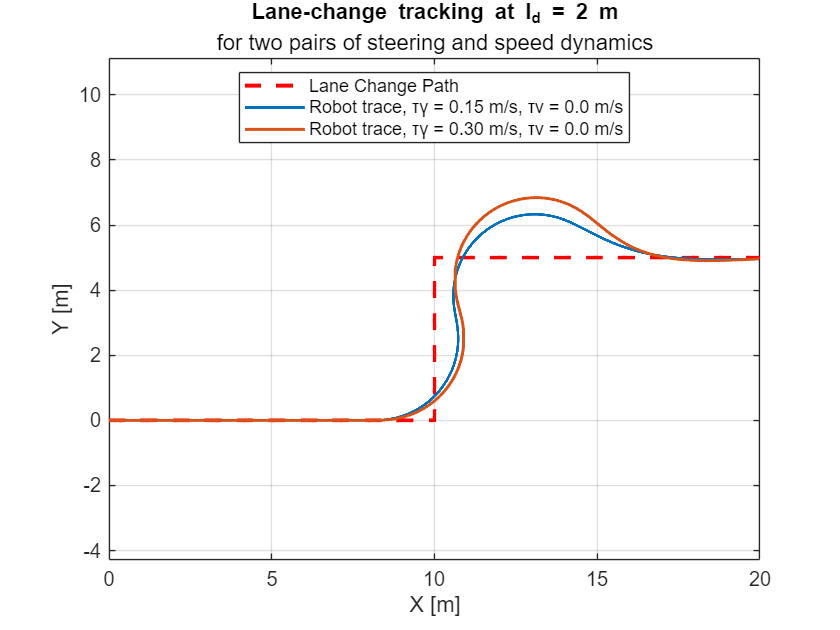

saveas(gcf, "figs/trace_d2.png")

3. Tighten the steering angle constraint (e.g., γmax = 35o ) and discuss effects. Hint: “Discussing errors” can be qualitative, but must also involve quantifying the behavior with error statistics (mean, max, 95%, RMS).

%
clear all;
clc;

% Global time parameters
global dt DT;
dt = 0.001;   % integration time step
DT = 0.01;    % control update step
T = 300.0;     % max simulation time
time_vec = 0:DT:T;

% Vehicle & control parameters
L = 2.5;               % wheelbase
Ld = 2.0;              % look-ahead distance

gamma_max = [deg2rad(25), deg2rad(35), deg2rad(45)]; % sweep gamma_max
v_max = 1;
v_min = 0;
goal_tol = 0.05;
tau_v = 0;
tau_gamma = 0;


% Initial state [x; y; theta; gamma; v]
q = [0; 0; 0; 0; 1];
% Generate the lane-change path
init_point = [0; 0];

% Mesh Resolution
dx = 0.01;
dy = 0.01;
seg_hor = 0:dx:10;
seg_ver = 0:dy:5;

% Segment 1: horizontal (0,0) -> (10,0)
path_1 = init_point + [seg_hor; zeros(1, length(seg_hor))];

% Segment 2: Vertical (10,0) -> (10,5)
x1 = path_1(1, end);
y1 = path_1(2, end);
path_2 = [x1; y1] + [zeros(1, length(seg_ver)); seg_ver];

% Segment 3: horizontal (10,5) -> (20,5)
x2 = path_2(1, end);
y2 = path_2(2, end);
path_3 = [x2; y2] + [seg_hor; zeros(1, length(seg_hor))];

% Concatenate the paths (drop the dupcate points)
path = [path_1, path_2(:,2:end), path_3(:,2:end)]';


% Store results
q_trace = zeros(length(time_vec), 5);
cte_trace = zeros(length(time_vec), 1);

% Robot trace on lane change path
figure;
plot(path(:, 1), path(:, 2), 'r--', 'LineWidth', 2, 'DisplayName', "Lane Change Path"); 
hold on;
cmap = lines(length(gamma_max));
for i = 1:length(gamma_max)
    % reinstate Initial state
    local_gamma_max = gamma_max(i);
    q = [0; 0; 0; 0; 1];
    q_trace = zeros(length(time_vec), 5);
    cte_trace = zeros(length(time_vec), 1);

    % State bounds
    Qmax = [inf; inf; inf; local_gamma_max; v_max];
    Qmin = [-inf; -inf; -inf; -local_gamma_max; v_min];

    for k = 1:length(time_vec)
        % Control update
        [gamma_d, cte] = purePursuitController(q, L, Ld, path);
        u = [gamma_d; 1.0];  % desired steering angle, constant velocity
        
        % Propagate dynamics using your robot model
        q = robot_bike_dyn(q, u, [-local_gamma_max; v_min], [local_gamma_max; v_max], Qmin, Qmax, L, tau_gamma, tau_v);
    
        % Store data
        q_trace(k, :) = q';
        cte_trace(k) = cte;
        % goal check
        if norm(q(1:2) - path(end,:).') < goal_tol || q(1) > path(end, 1)
            q_trace = q_trace(1:k,:);   % trim unused rows
            break                        % leave the loop
        end
    end
    plot(q_trace(:,1), q_trace(:,2), 'b', 'LineWidth', 1.5, 'Color', cmap(i,:), 'DisplayName', sprintf('Robot trace, \\gamma_{max} = %.0f degree', round(rad2deg(gamma_max(i)))));
    xlabel('X [m]'); ylabel('Y [m]');
    title('Lane-change tracking at l_d = 2 m', 'for two pairs of steering and speed dynamics');
    legend("Location", "best")
    axis equal;
    grid on;
    hold on;

    % Quantitative Analysis
    abs_cte = abs(cte_trace);                      % magnitude of the error
    
    % Numerical metrics
    cte_mean  = mean(abs_cte);                     % arithmetic mean
    cte_max   = max(abs_cte);                      % maximum value
    cte_p95   = prctile(abs_cte, 95);              % 95th percentile
    cte_rms   = rms(abs_cte);                      % root-mean-square
    
    fprintf('\nCTE statistics gamma_{max} = %.0f degree', round(rad2deg(gamma_max(i))));
    fprintf('  Mean      : %.4f\n', cte_mean);
    fprintf('  Max       : %.4f\n', cte_max);
    fprintf('  95th perc : %.4f\n', cte_p95);
    fprintf('  RMS       : %.4f\n', cte_rms);
end


CTE statistics gamma_{max} = 25 degree

  Mean      : 0.4980


  Max       : 2.5283


  95th perc : 1.9924


  RMS       : 0.8537



CTE statistics gamma_{max} = 35 degree

  Mean      : 0.4813


  Max       : 1.8121


  95th perc : 1.7336


  RMS       : 0.7922



CTE statistics gamma_{max} = 45 degree

  Mean      : 0.1819


  Max       : 0.8546


  95th perc : 0.7533


  RMS       : 0.3176


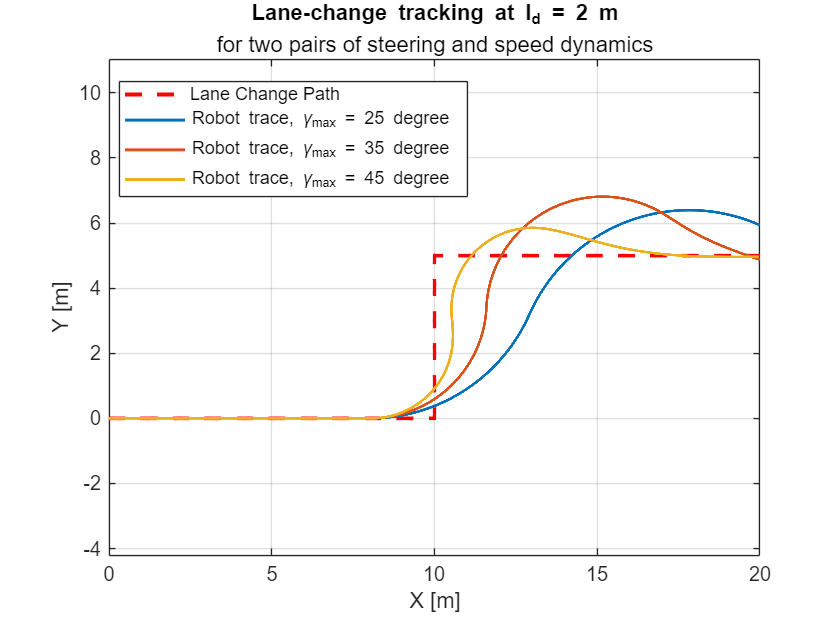

saveas(gcf, "figs/trace_d3.png")